# Plantilla problema práctica 1 Model. Exp.

Es necesario cargar los datos suministrados por la empresa en este punto

load data4.mat

## Petición de la empresa

Cordial saludo ingenieros matemáticos. Nos comunicamos con ustedes porque necesitamos determinar un modelo para el comportamiento de cierta planta ultra secreta. Como podrán comprender, nos vemos en la obligación de reservarnos la mayor cantidad de información posible. Nosotros mismos ya hemos adelantado parte de los procesos necesarios para determinar el modelo. Sabemos que nuestra planta consta de una única entrada y una única salida, la entrada tiene un valor de 1000 unidades regularmente y la planta se mantiene en estado estacionario. Partiendo de este punto de estabilidad, nuestro anterior ingeniero varió el valor de la entrada en un rango de 500 a 1500 tal y como pueden ver a continuación

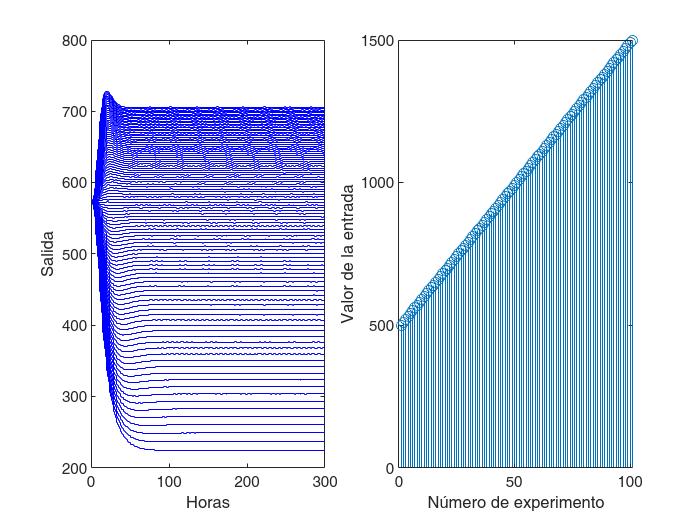

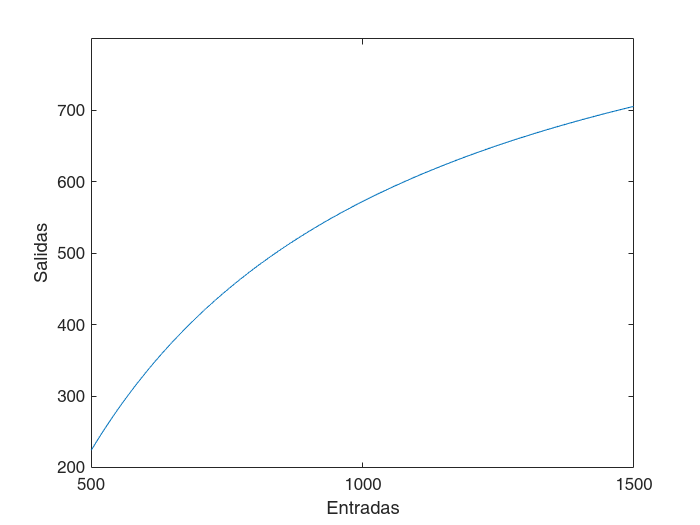

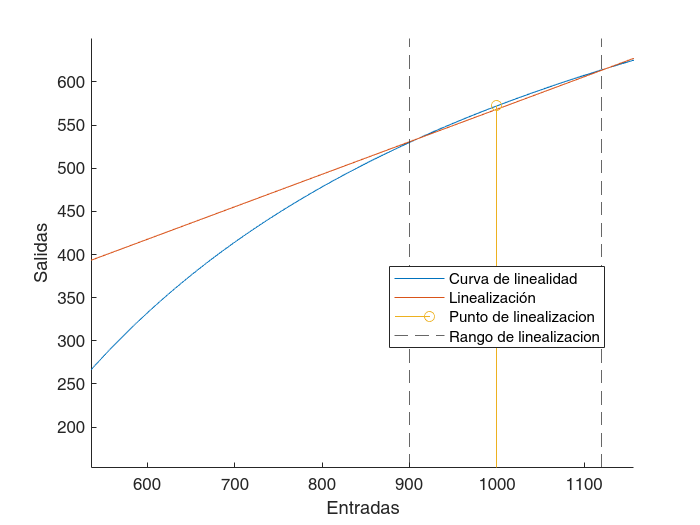

figure(1)
clf
subplot(1,2,1)
stairs(0:300,y_sample','b')
xlabel('Horas')
ylabel('Salida')
subplot(1,2,2)
stem(u_lineal)
xlabel('Número de experimento')
ylabel('Valor de la entrada')

Esta información se las compartimos a través de la matriz **y_sample** y el vector **u_lineal**. La primera fila de la matriz corresponde con el primer valor del vector como entrada. Para cada caso, se tomaron muestras del estado del sistema cada hora y esperamos hasta que el sistema se estabilizara. Luego, para un solo experimento, se aumentó lo máximo posible el esfuerzo de muestreo y se cambió la entrada del sistema de 1000 a 1120 de forma abrupta. Los datos de la respuesta del modelo se presentan a continuación

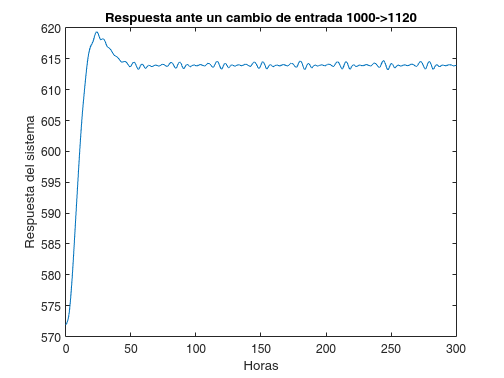

Tsi = 10.6000

Tss = 21.2000

figure(2)
clf
plot(t,y_response)
xlabel('Horas')
ylabel('Respuesta del sistema')
title('Respuesta ante un cambio de entrada 1000->1120')

Con base en dicha información, nuestro anterior ingeniero decidió excitar el sistema con un periodo de muestreo de 1 hora y una señal PRBS (con un periodo igual al de muestreo) que variaba entre valores de 900 y 1120 para luego proceder a identificar un modelo apropiado para la planta, sin embargo, tuvimos que prescindir del ingeniero en este punto y el sistema no ha podido identificarse. Los datos recopilados se muestran a continuación

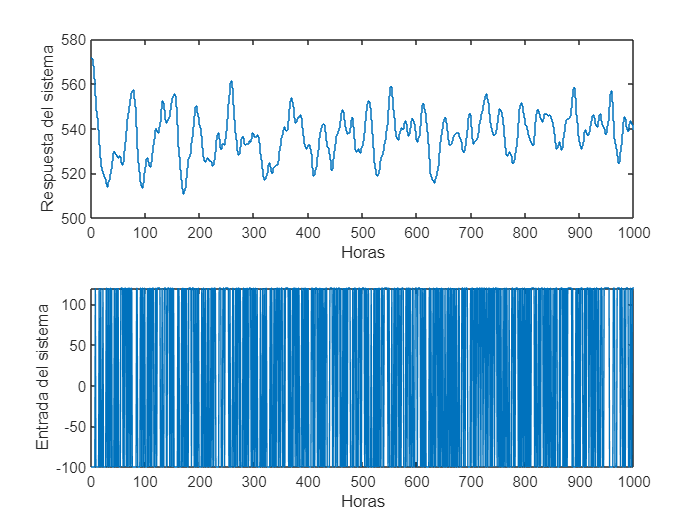

figure(3)
clf
subplot(2,1,1)
stairs(0:1000,y')
xlabel('Horas')
ylabel('Respuesta del sistema')
subplot(2,1,2)
plot(0:1000,u)
xlabel('Horas')
ylabel('Entrada del sistema')

Nos hemos contactado con ustedes con la esperanza de que puedan evaluar la metodología que siguió nuestro anterior ingeniero (si es adecuada o si modificarían algo) y, en caso de que lo consideren posible, concluir el proceso de identificación del sistema. Les solicitamos el mayor detalle posible en sus respuestas así como en la justificación de porqué deberíamos confiar o no en el modelo que ustedes puedan identificar. Estaremos muy atentos. 

## Respuesta a la empresa

A continuación desarrolle lo que la empresa le ha pedido.

#### Revision rango de linealizacion

Se revisa la curva de linealizacion.

clf
ylin =  y_sample(:, end-50 : end);
ylinmean = mean(ylin,2);

plot(u_lineal,ylinmean)
xlabel('Entradas')
ylabel('Salidas')

Como el sistema es no lineal se procede a linealizar el sistema en u = 1000 y se revisan el rango de linelaizacion tomado por el ingeniero.

puntoConf = ylinmean(50); puntoConfAnt = ylin(49);
puntoConfDesp = ylin(51);
m1 = (puntoConfDesp-puntoConf);
m2 = (puntoConf-puntoConfAnt);
m = mean([m1 m2]);
syms x
tangente = m*x-m*50+puntoConf;
y2 = subs(tangente,x,0:1:100);

clf
hold on
plot(u_lineal,ylinmean)
plot(u_lineal, y2)
stem(1000,ylinmean(u_lineal==1000));
xline(1120,"--"); xline(900,'--')
legend({'Curva de linealidad', ...
        'Linealización', ...
        'Punto de linealizacion', ...
        'Rango de linealizacion'},"Location","best")
xlabel('Entradas')
ylabel('Salidas')

#### Periodo de muestreo

puntoEq = mean(y_response(end-100:end))-y_response(1);
tenP = find(y_response>=(puntoEq/10)+y_response(1));
tenP = tenP(1);
ninetyP = find(y_response >= ((puntoEq*9)/10)+ y_response(1));
ninetyP = ninetyP(1);
Ts = ninetyP-tenP;
Tsi = Ts/10
Tss = Ts/5

Se encuentra que hay un el rango para muestrear el sistema es aproximadamente entre 1 y 2 horas.

#### Estimacion del sistema

Esta parte esta realizada en parte en el documero Practica1.sid y la verificacion aca

data = iddata(y,u');
advice(data)

General data characteristics:
-----------------------------
This is a time domain data set with 1 input(s) and 1 output(s), 1001 samples 
and 1 experiment(s).

All inputs in the data have been denoted as 'zero order hold' ('zoh'), i.e. 
they are assumed to be piecewise constant over the sample time.
If the input is a sampled continuous signal and you plan to build or convert to 
continuous-time models, it is recommended to mark the InterSample property as 
'First order hold': Data.InterSample = 'foh' or Data.int = {'foh','foh', ...} 
for multi-input signals.

Some inputs and/or outputs have non-zero means. It is generally recommended to 
remove the means by DAT = DETREND(DAT), except in the following cases:
1. The signals are measured relative to a level that corresponds to a physical 
equilibrium. This could e.g. be the case if step responses are recorded from an 
equilibrium point. In this case, it is advisable to remove the equilibrium 
values rather than data means. You may do so u

pexcit(data)

ans = 50

delayest(data)

ans = 3

Ya que el tiempo sugerido de muestreo se estimo entre 1 y 2 horas, se hace la eliminacion de outliers con grupos de 10 datos (1 horas), para utilizar el tiempo de muestreo del ingeniero. De lo que se ve, ningun outlier fue detectado.

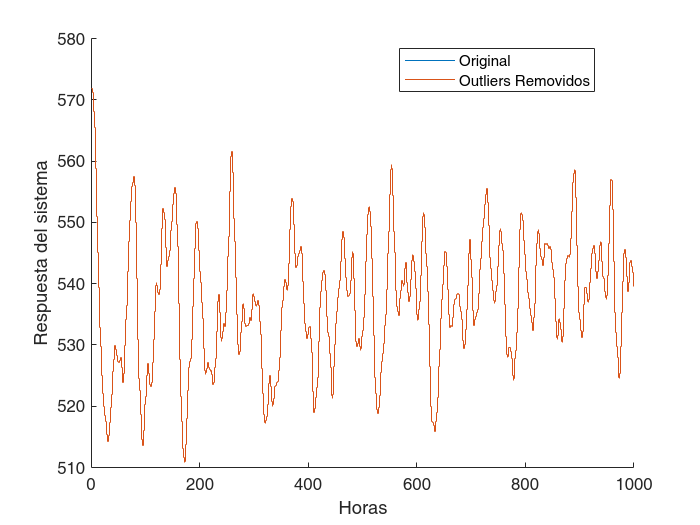

y1 = filloutliers(y,"spline","movmean",10);
clf
hold on
stairs(0:1000,y')
stairs(0:1000,y1')
xlabel('Horas')
ylabel('Respuesta del sistema')
legend({'Original', 'Outliers Removidos'},"Location","best")

Probando la deteccion de outliers con otro metodo igual encontramos que no hay outliers

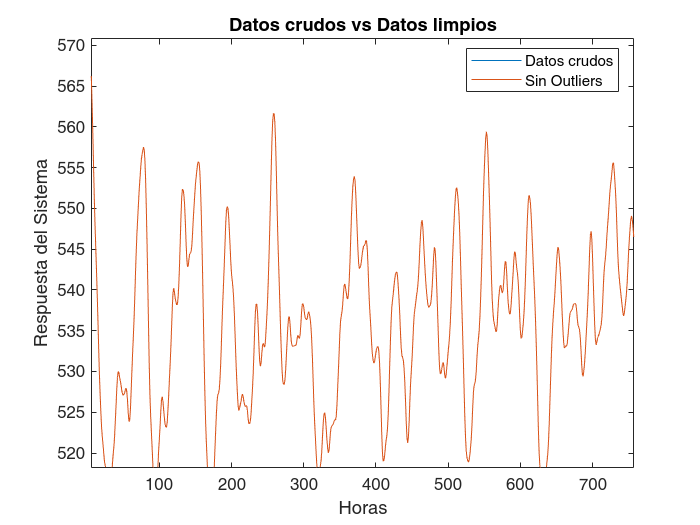

u=u';
clean_d= hampel(y);
clf
plot(0:1:1000,y)
hold on
plot(0:1:1000,clean_d)
xlabel('Horas')
ylabel('Respuesta del Sistema')
title('Datos crudos vs Datos limpios')
legend('Datos crudos','Sin Outliers','Location','best')

Se hace la eliminacion de medias pero como cambia la entrada el orden de excitacion del sistema ya no se mantendria igual por lo que no se va a utilizar este metodo para estimar el sistema.

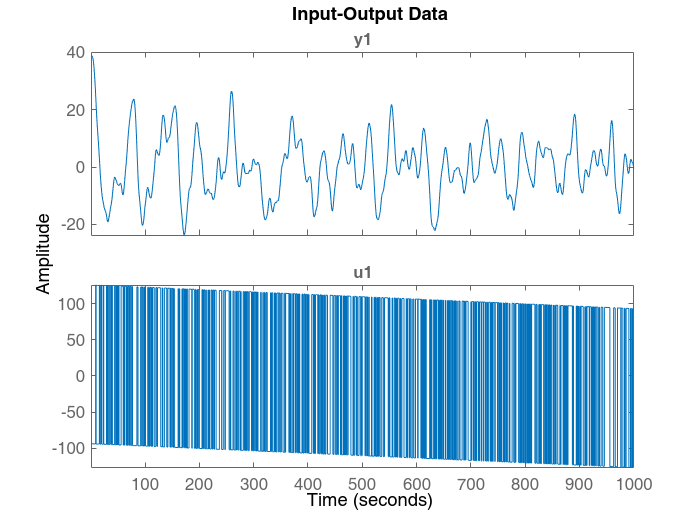

clf
MeanlessData = detrend(data,1);
plot(MeanlessData)

Se hace la eliminacion de tendencias y esta al mantener las caracteristicas de la entrada PRBS hacen que se vaya a utilizar este metodo para la identificacion de los sistemas, de la misma forma que lo hace el preprocesamiento de los datos en el SystemIdentification Toolbox

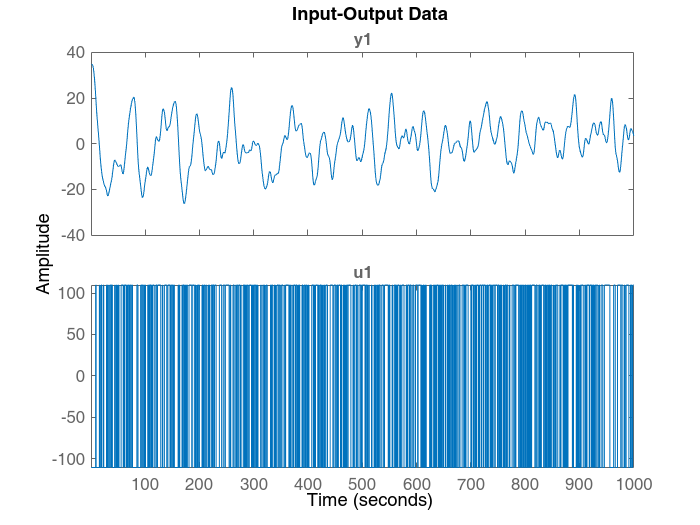

DetrendedData = detrend(data, 0);
plot(DetrendedData)

BJ Best Fit, 

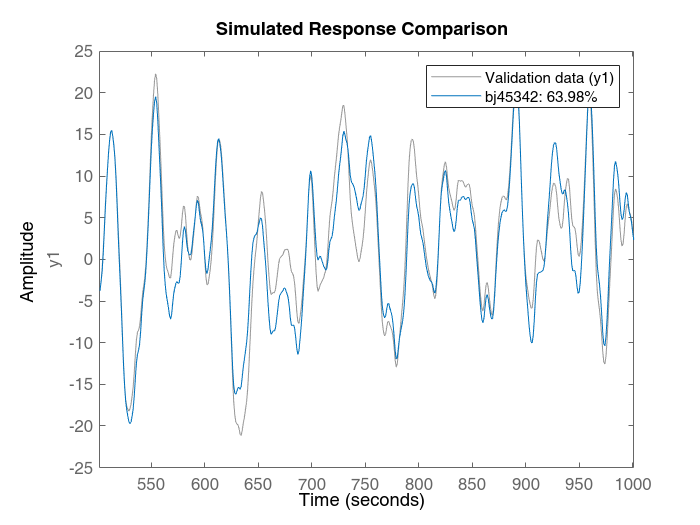

clf
Opt = bjOptions('Focus','prediction');                                                           
bj45342 = bj(DetrendedData(1:501),[4 5 3 4 2], Opt);
compare(DetrendedData(502:1001), bj45342)

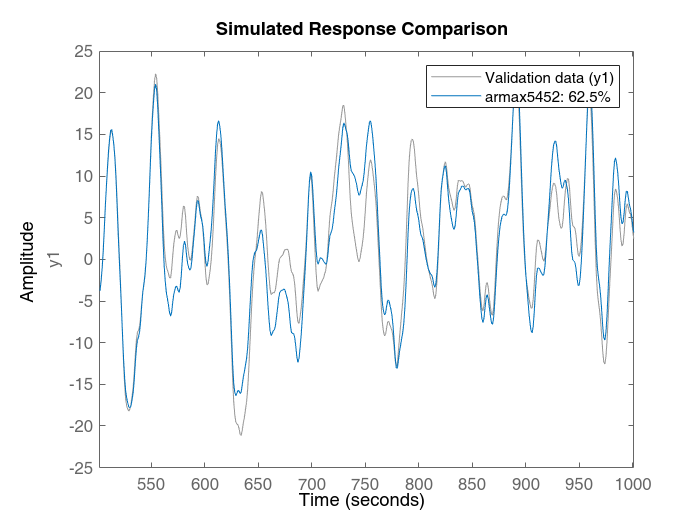

Opt = armaxOptions('Focus','prediction');                                                           
armax5452 = armax(DetrendedData(1:501),[5 4 5 2], Opt);
compare(DetrendedData(502:1001), armax5452)